# Analyzing Bike Motion 

## Bike Linear Acceleration

**QEA 3 Final Project:** Diana Garcia, An Grocki, Natsuki Sacks

This file serves as a walk-through of how we would analyze our data and explains how one could load data to MATLAB and run it through our algorithm. 

Once you have successfully collected data using the accelerometer (no gravity) from the PhyPhox app or equivalent, load the data into a CSV. Then, you can load the file. You can choose to clip the data to remove anything that wasn't collected while consistently biking. Your pace information will be more accurate this way, but if you choose to use the raw data, you will still get a relatively accurate result. 

%name of file in the same folder 
%load data
name = "60_stat.mat";
s = load(name);
c = struct2cell(s);
frequency_data = [c{:}];
%Clipped data
frequency_data = frequency_data(1:19000, :);
time = frequency_data(:,1); 
x = frequency_data(:,2);
y = frequency_data(:,3);
z = frequency_data(:,4);

X_max_acceleration = max(x);
Y_max_acceleration = max(y);
Z_max_acceleration = max(z);
X_min_acceleration = min(x);
Y_min_acceleration = min(y);
Z_min_acceleration = min(z);

Based on our motion model, the z-axis is up and down, the y-axis is left to right, and the x-axis is out of the pedal. Based on the motion of the bike pedal, we would assume that the z-axis has the greatest magnitude, followed by the y-axis. The x-axis would have the smallest magnitude since the bike pedal ideally doesn't have freedom to move about the x-axis. 

The following conditional confirms this assumption. 

if (Z_max_acceleration > Y_max_acceleration) > X_max_acceleration
    disp("True, Z>Y>Z")
end 

### Visualizing the Data

The following graphs the x, y, and z-axes vs. time and shows the minimum and maximum acceleration of each.

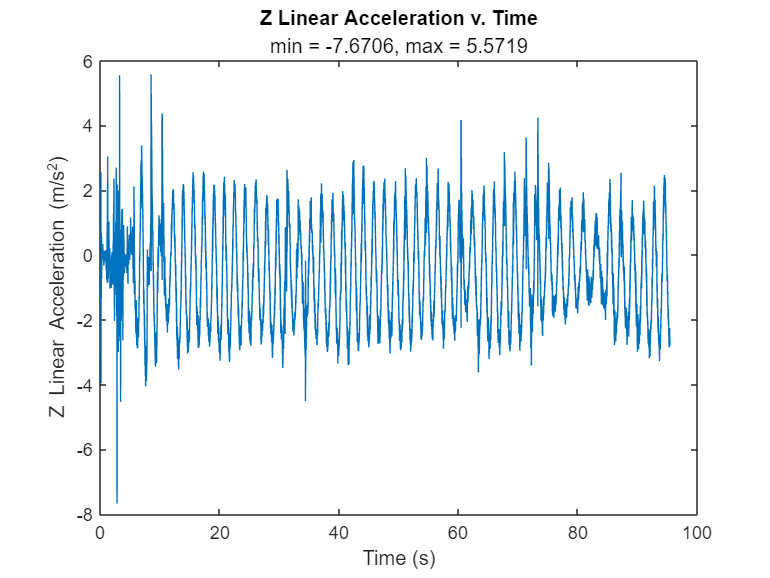

%Z graph
plot(time,z)
title("Z Linear Acceleration v. Time")
subtitle("min = " + Z_min_acceleration + ", max = "+ Z_max_acceleration)
xlabel("Time (s)");
ylabel("Z Linear Acceleration (m/s^2)");

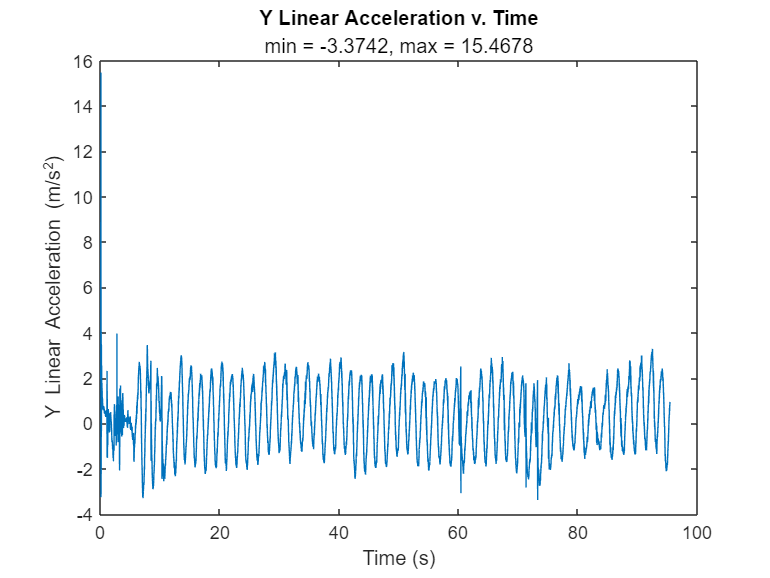

%Y Graph
plot(time,y)
title("Y Linear Acceleration v. Time")
subtitle("min = " + Y_min_acceleration + ", max = "+ Y_max_acceleration)
xlabel("Time (s)");
ylabel("Y Linear Acceleration (m/s^2)");

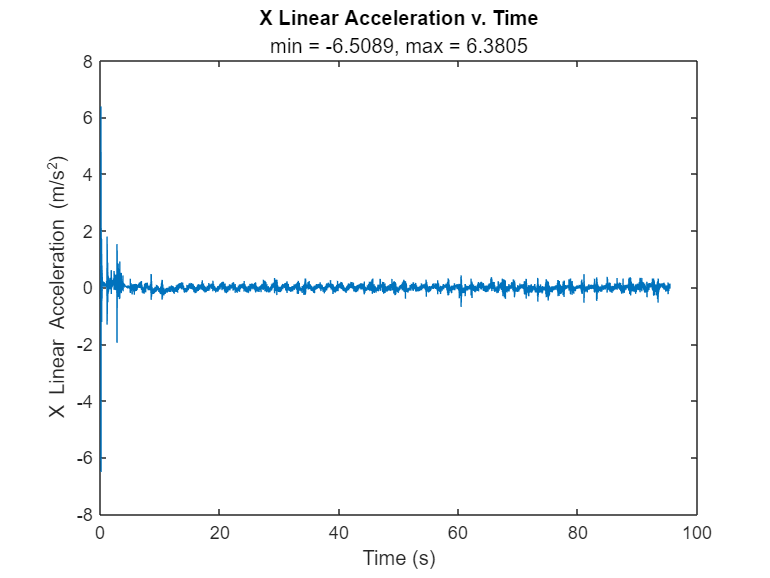

% X Graph
plot(time,x)
title("X Linear Acceleration v. Time")
subtitle("min = " + X_min_acceleration + ", max = "+ X_max_acceleration)
xlabel("Time (s)");
ylabel("X Linear Acceleration (m/s^2)");

Based on the motion model, the y-axis and z-axis data should be offset sinosidal waves. We clipped the data down to make this phase shift more apparent. 

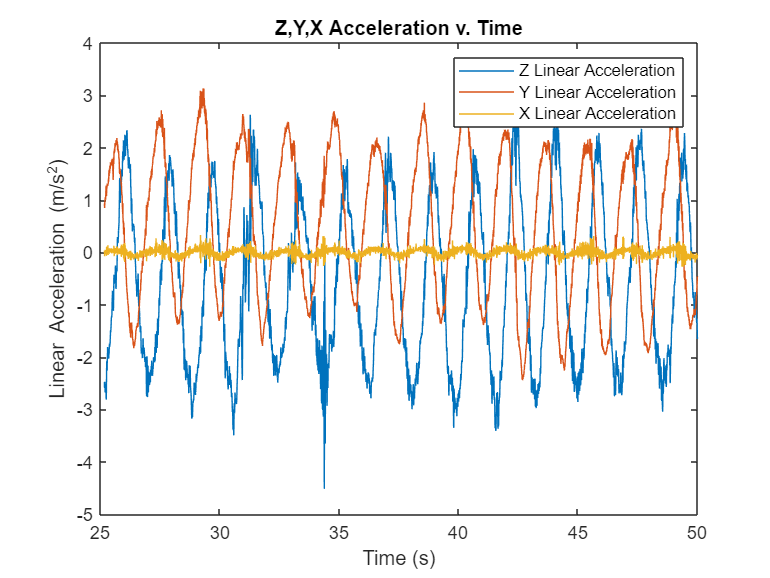

%Graph X and Y
clipped_frequency_data = frequency_data(5000:10000, :);
t_clipped = clipped_frequency_data(:,1);
x_clipped = clipped_frequency_data(:,2);
y_clipped = clipped_frequency_data(:,3);
z_clipped = clipped_frequency_data(:,4);

plot(t_clipped, z_clipped)
hold on
plot(t_clipped, y_clipped)
plot(t_clipped, x_clipped)
ylabel("Linear Acceleration (m/s^2)")
xlabel("Time (s)")
title("Z,Y,X Acceleration v. Time")
xlim([25 50]);
legend("Z Linear Acceleration", "Y Linear Acceleration","X Linear Acceleration")
hold off

### Analyzing the Data

Now that we know that our linear acceleration looks like what we would expect, we can move on to finding the frequencies. In order to find our frequencies, we have to find do the Fourier transofrm on our data. A detailed explanation of how this works is on our website. 

The Fourier transform will give the dominant frequency of the data and will give us the bike's pace in terms of Hz.

max_freq = zeros([1 3]);
bpm = [60 90 120];
[max_mag, max_freq(1)] = max_freq_plot(frequency_data, 0);
[max_mag, max_freq(2)] = max_freq_plot(x90_stationary, 0);
[max_mag, max_freq(3)] = max_freq_plot(x120_stationary, 0);

Since the max_freq will give us the dominant frequency in terms of Hz (rotations per second), we want to multiply that by 60 to get our units into cycles per minute.

max_freq(1) = max_freq(1) * 60;
max_freq(2) = max_freq(2) * 60;
max_freq(3) = max_freq(3) * 60;

% Display paces for each bpm
for i = 1:3
    disp("Pace (rev/min) for " + bpm(i) + " is " + max_freq(i))
end

Pace (rev/min) for 60 is 33.3063
Pace (rev/min) for 90 is 46.1148
Pace (rev/min) for 120 is 57.5157


This pace is what we would expect, since it should take two beats to complete a revolution. For 60 BPM on a stationary bike, we are getting 33.3063 revolutions per minute. This is extradordinarily slow for the typical biker, but this is for the foundation of our analysis. 

### Providing Feedback

To provide feedback to the bicyclist, we created conditionals to check if the bicyclist was going slower, faster, or around their target pace. 

target = 60/2; % rev/min
avg_revs = max_freq(1); % max_freq for 60 BPM 
check_pace(target, avg_revs)

Woah, buddy! Slow down! You're going 3.3063 rev/min too fast at a target of 30 rev/min.


### Testing with Moving Data

Let's test the data that we received from Diana's moving bike. She attempted to bike at 60, 90, and 120 BPM. Say that we set a target at 60 BPM, or 30 rev/min. Let's see what the algorithm would have to say about that...

max_freq = zeros([1 3]);
[max_amps, max_freq(1)] = max_freq_plot(x60_moving, 0);
[max_amps, max_freq(2)] = max_freq_plot(x90_moving, 0);
[max_amps, max_freq(3)] = max_freq_plot(x120_moving, 0);
max_freq = max_freq .* 60

max_freq =    30.5497   50.7955   60.5674


% Check pace for various datasets with a target of 50 rev/min
check_pace(50, max_freq(1))

Speed up, grandpa! You're going 19.4503 rev/min too slow at a target of 50 rev/min.


check_pace(50, max_freq(2))

You're doing great, sweetie :)


check_pace(50, max_freq(3))

Woah, buddy! Slow down! You're going 10.5674 rev/min too fast at a target of 50 rev/min.
